# Chemical Reaction Kinetics: Theoretical Backgrounds

## Table of Contents

## Introduction

A general chemical reaction can be represented as:


$$\textrm{aA}+\textrm{bB}+\ldotp \ldotp \ldotp \to \textrm{xX}+\textrm{yY}+\ldotp \ldotp \ldotp$$


where

start to writting

A *A*, B, etc. are the reactants, and X, Y, etc. are the products. a, b, x, y represent stoichiometric coefficients. 

The general reaction law can be expressed using differential equations as below:


$$r={\textrm{kc}}^n$$


*k *is the **rate constant**, a positive coefficient whose units for a first order reaction are $\frac{1}{s}$. 

For reactants, a −sign on the left half of the equation represents the rate of disappearance for reactants, while it takes a +sign for the rate of generation of the products. 

*n* is the order of the reaction.

## Explore the rate constant unit for other reaction rates

When the reaction rate is n:

n=1; %

the rate constant has the following unit:

u = symunit;
r = 1*u.mol/u.m^3/u.s;
c = 1*u.mol/u.m^3;
disp(r/c^n)

$$\frac{1}{s}$$

%

## Kinetic Equations of various orders

Let the rate constant wiil be equal to

k=0.5; %
c0=2; %

### First Order Reaction

#### Numerical solution of the first order kinetic reaction

The kinetic equation of the first order reaction is when the index $n=1$. Let us inspect the numerical solution of the model with the rate constant $k$ and initial concentration $c_0$:

%

% Define ODE problem and specify solver options
odeObj2 = ode(ODEFcn = @firstOrderKinetics, ...
    InitialValue = c0, ...
    Parameters = k);

% Solve ODE problem
solution = solve(odeObj2,0,20);
clear odeObj2
%

#### Half-lives of first order reactions

When the concentration of the reactant will be equal to the half of the initial concentration,


$$c\left(t_h \right)=\frac{c_0 }{2}$$


The $t_h$ is a time in which the concentration is decreased twice and it is called as half-life.

When the kinetic reaction is first order, the half-life is constant and independent from the initial concentration.

#### Constant half-lives

When the reaction is first order, the following half-lives of the reaction (when $c=\frac{c_0 }{2},\frac{c_0 }{4},\frac{c_0 }{8},\frac{c_0 }{16}\ldotp \ldotp \ldotp$) should stay the same. Let us inspect these times by interpolation of already computed numerical solution of the model:

time = solution.Time;
c = solution.Solution;
Cint = c0.*[1 1/2 1/4 1/8 1/16];
Tint = interp1(c,time,Cint);
results = table(Tint', Cint','VariableNames',["Time" "Concentration"])

results = 5×2 table
     Time     Concentration
    ______    _____________

         0            2    
    1.3956            1    
    2.7771          0.5    
    4.1685         0.25    
    5.5492        0.125    


The solution plot indicates interpolated points.

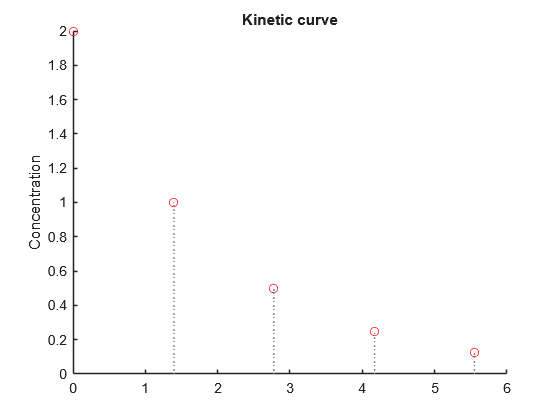

 for i=2:length(Cint)
    hold on
    line([Tint(i) Tint(i)],[0 Cint(i)],"Color",[0.5 0.5 0.5],"LineStyle",":")
 end
 hold on
 plot(Tint,Cint,"LineStyle","none","Marker","o","MarkerEdgeColor","red")
 legend("hide")
hold off
title("Kinetic curve")

ylabel("Concentration")

Exploring times we can extract values of the following half-lives:

 th(1)=NaN;
for i=2:length(Cint)
    th(i)=Tint(i)-Tint(i-1);
end
results = [results table(th','VariableNames',"Half Lives")]

results = 5×3 table
     Time     Concentration    Half Lives
    ______    _____________    __________

         0            2             NaN  
    1.3956            1          1.3956  
    2.7771          0.5          1.3815  
    4.1685         0.25          1.3915  
    5.5492        0.125          1.3806  


The overall half-life value may be represented by a mean:

mth = mean(th,"omitnan");
sth = std(th,"omitnan");
disp("Thalf = "+mth+" +/- "+sth)

Thalf = 1.3873 +/- 0.0074094


#### Exercise

Try to handle with $k$ and $c_0$ values. What is the difference between them? 

#### Analytical Solution as an Explanation

The truth solution may be covered by using symbolic expression

syms k_s c_s(t) c_s0
rs = diff(c_s,t) == - k_s*c_s^n

$$rs(t) = \frac{\partial }{\partial t}c_{s}\left(t\right)=-k_{s}\,c_{s}\left(t\right)$$

The analytical ODE solution is as follows:

Csol = dsolve(rs,c_s(0)==c_s0)

$$Csol = c_{\mathrm{s0}}\,{\mathrm{e}}^{-k_{s}\,t}$$

The analytical $t_h$ value may be achieved be solving the following equation:

Ceqn = Csol == 0.5*c_s0

$$Ceqn = c_{\mathrm{s0}}\,{\mathrm{e}}^{-k_{s}\,t}=\frac{c_{\mathrm{s0}}}{2}$$

% Compute analytic solution of a symbolic equation
t_ha = solve(Ceqn,t);
% Display symbolic solution returned by solve
displaySymSolution(t_ha);

$$t\_ha = \frac{\log\left(2\right)}{k_{s}}$$


% Exercise for workshops participants
% 1) Define Ceqn
% 2) Solve Eqn by using Live Task
% 3) Show the outcoming expression to cover the text

#### Quiz

**Choose the proper ticks:** For the first order reaction the half life is **not related** to value of: 

answer(1)=false;
answer(2)=false;
answer(3)=false;
 
if answer == [1 0 1]
    disp("The answer is correct")
else
    disp("The answer is incorrect. Look at the analytical expression and try again.")
end

The answer is incorrect. Look at the analytical expression and try again.


#### Model linearization

The analytical solution of first order kinetics equation can be linearized by logarithmizing of the equation:

logC = log(Csol)

$$logC = \log\left(c_{\mathrm{s0}}\,{\mathrm{e}}^{-k_{s}\,t}\right)$$

% Compute simplified symbolic expression
log_C = expand(logC,"IgnoreAnalyticConstraints",true)

$$log\_C = \log\left(c_{\mathrm{s0}}\right)-k_{s}\,t$$

Because the $c_0$ and $k$ parameters are independent of time, the form of the equation should be represented by a straight line. Try to plot it:

log_C(t) = subs(log_C, {k_s,c_s0},{k, c0});

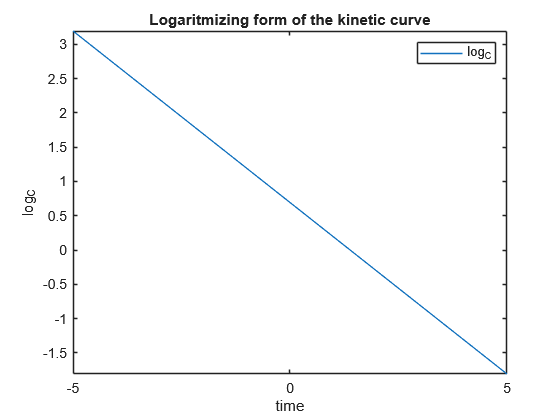

% Create fplot of selected data
fp = fplot(log_C,"DisplayName","log_C");

% Add ylabel, title, and legend
ylabel("log_C")
title("log_C")
legend

ylabel("log_C")
xlabel("time")
title("Logaritmizing form of the kinetic curve")

### Second Order Reaction

The second order reaction rate is related to the reactant concentration powered by 2:


$$r=\pm {\textrm{kc}}^2$$
  

#### Task to do: Half-lives in Second Order Reaction

The table of following half-lives of the second order reaction are presented following the reaction plots. Look at these data. Try to manipulate with model parameters by using control panels in the beginning of the document. Discuss with other students your about your observations and try to figure out following problems:

1) What are the differences between half-lives values of reaction of second order kinetics and first order kinetics?

2) Is the half-life value useful to describe such type of kinetics?

3) What does the experimental measurement of the half-life of the reaction bring to the kinetic analysis of the system?

/We may think about potential problems that may be implemented to the section during this workshops. These questions are only the example/ 

function r = secondOrderReactionRate(~, c, par)
k = par;
r = -k*c^2;
end
% Define ODE problem and specify solver options
odeObj = ode(ODEFcn = @secondOrderReactionRate, ...
    InitialValue = c0, ...
    Parameters = k);

% Solve ODE problem
solData2 = solve(odeObj,0,20,Refine = 6);
clear odeObj
c2 = solData2.Solution;
time2 = solData2.Time;
% Create plot of time and c
 h3 = plot(time2,c2,"DisplayName","c");
% 
 % Add xlabel, ylabel, title, and legend
 xlabel("time")
 ylabel("c")
 title("Reactant concentration over the time when k = "+k+"m3/mols")

T2int = interp1(c2,time2,Cint);
results2 = table(T2int', Cint','VariableNames',["Time" "Concentration"])

results2 = 5×2 table
     Time     Concentration
    ______    _____________

         0            2    
    1.0023            1    
    3.0063          0.5    
    7.0109         0.25    
     15.01        0.125    



th2(1)=NaN;
 for i=2:length(Cint)
     th2(i)=T2int(i)-T2int(i-1);
 end
 results2 = [results2 table(th2','VariableNames',"Half Lives")]

results2 = 5×3 table
     Time     Concentration    Half Lives
    ______    _____________    __________

         0            2             NaN  
    1.0023            1          1.0023  
    3.0063          0.5           2.004  
    7.0109         0.25          4.0046  
     15.01        0.125          7.9988  


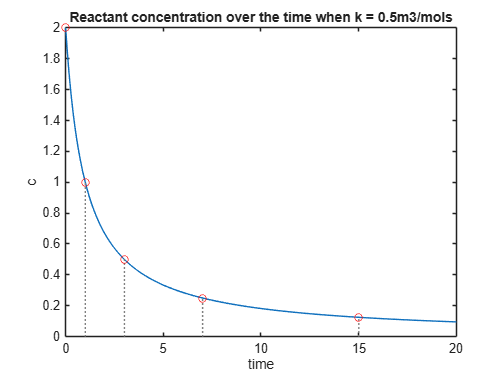


  for i=2:length(Cint)
     hold on
     line([T2int(i) T2int(i)],[0 Cint(i)],"Color",[0.5 0.5 0.5],"LineStyle",":")
 end
 hold on
 plot(T2int,Cint,"LineStyle","none","Marker","o","MarkerEdgeColor","red")
 legend("hide")
hold off

#### Analytical approach

The analytical solution of the second order reaction is as follows:

syms k2_s c2_s(t) c_s0
rs2 = diff(c2_s,t) == - k2_s*c2_s^2;
C2sol = dsolve(rs2,c2_s(0)==c_s0)

$$C2sol = \frac{c_{\mathrm{s0}}}{c_{\mathrm{s0}}\,k_{2,s}\,t+1}$$

#### Task to do: second order model linearization

Propose the substitusion of the function to get the linear form. You may use standard mathematical operations or functions. Provide it in the Edit Field. Verify whether the finalForm is linear.

Y2 = C2sol;
finalForm(t) = expand(Y2)

$$finalForm(t) = \frac{c_{\mathrm{s0}}}{c_{\mathrm{s0}}\,k_{2,s}\,t+1}$$

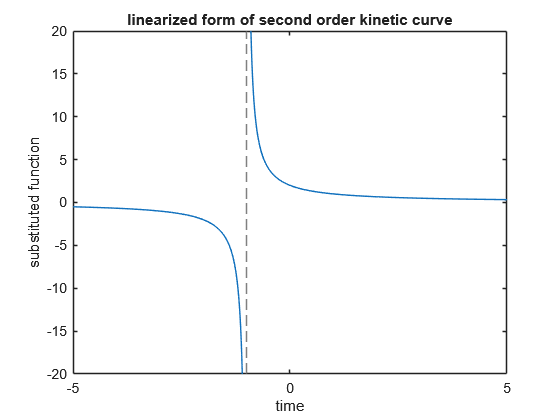

finalForm(t)=subs(finalForm,{k2_s c_s0},{k c0});
fplot(finalForm)
xlabel("time")
ylabel("substituted function")
title("linearized form of second order kinetic curve")

## Key takeaways

- **Kinetic equations** express the relation between the reactant concentration and the chemical process rate

- The exponent value of concentration corresponding to the **kinetics order**

- **The first order reaction **is characterized by **a constant half-lives**. The analytical solution exhibits that its value is not correlated to the concentration value of reactant. Instead of it, the reaction going through the **second order kinetics **does not indicate such a phenomenon

- **Both first and second order** kinetic equations **are able to be linearized** by using standard mathematical methods

function r = firstOrderKinetics(t,c,k)
% This function returns the right-hand side of the ODE: dy/dt = f(t,y,p)
r = -k*c;
end

Copyright 2016 - 2017 The MathWorks, Inc.